# Plots for panels of Figure SI.1.5

## To run this code, you will need to install the **Signal Processing Toolbox** by MathWorks; if you do not already have this installed, MatLab will give you an error that will direct you to the Add-On Explorer page from where you can install the **Signal Processing Toolbox**

## Figure SI.1.5A

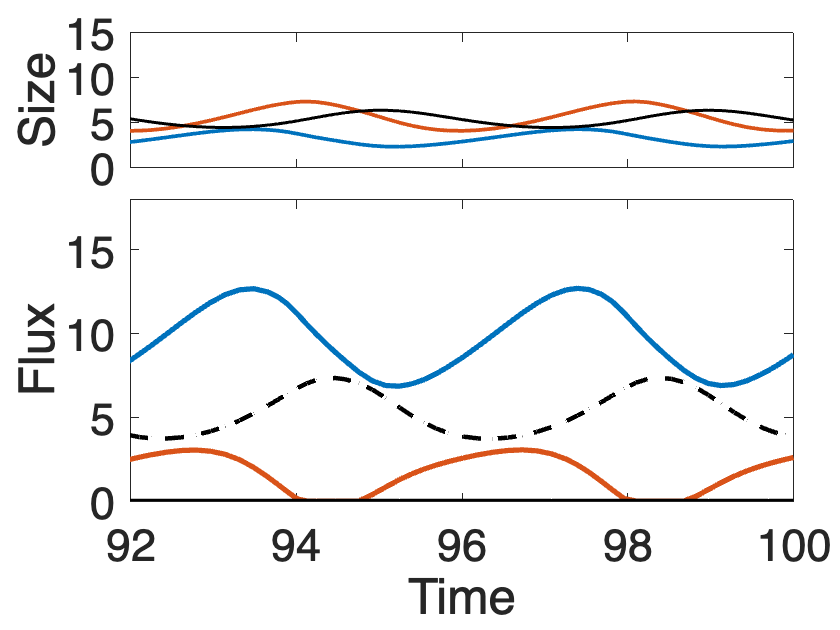

clear

%%% UNSTABLE
f = 3;
uJ = 0.5;
m = 2.5;
beta = 0.18;
a = 0.5;
mI = 1.5;
uA = 0.5;
mb = 0.2;
mbI = mb;

 N = ones(3,1);
 T_interval = [0, 100];
 Init_conditions = [9; 0.1; 3].*N;
    
[T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
[pksJS,locsJS] = findpeaks(N(:,1),T);
[pksJI,locsJI] = findpeaks(N(:,2),T);
[pksA,locsA] = findpeaks(N(:,3),T);
[pksJS2,locsJS2] = findpeaks(max(N(:,1))-N(:,1),T);
[pksJI2,locsJI2] = findpeaks(max(N(:,2))-N(:,2),T);
[pksA2,locsA2] = findpeaks(max(N(:,3))-N(:,3),T);


% plot(T,N, "LineWidth",3)
% hold on
% % xline(locsJS(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% legend("JS", "JI", "A")
% xlim([92 100])
% xlabel("Time")
% ylabel("Abundance")
% set(gca, 'FontSize', 30)
% hold off

colors = get(gca,'ColorOrder');
NN = N(:,1)+N(:,2);
NS = max(m-mb.*(NN),0);
NI = max(mI-mbI.*(NN),0);

tiledlayout(3,1,'TileSpacing','Compact', "Padding",'Compact')
nexttile
plot(T,N(:,1),"LineWidth",2.5, 'Color', colors(2,:))
hold on
plot(T,N(:,3),"LineWidth",2.5, 'Color', colors(1,:))
plot(T,N(:,2),"LineWidth",2, 'Color', "k")
xlim([92 100])
ylim([0 15])
%xlabel("Time")
ylabel("Size")
set(gca, 'FontSize', 30, 'Xticklabel',[])
%legend("J_S", "J_I", "A")
hold off

nexttile([2,1])
plot(T, NS.*N(:,1),"LineWidth",3.5, 'Color', colors(2,:)) %, "LineStyle","--") %% Total flux
hold on
plot(T, NI.*N(:,2),"LineWidth",3, 'Color', "k") %, "LineStyle","--") %% Total flux
plot(T, f*N(:,3),"LineWidth",3.5, 'Color', colors(1,:)) %, "LineStyle","--") %% Total flux
plot(T, beta*N(:,1).*N(:,2),"LineWidth",3, 'Color', "k", "LineStyle", "--") %, "LineStyle","--") %% Total flux
xlim([92 100])
ylim([0 18])
xlabel("Time")
ylabel("Flux")
set(gca, 'FontSize', 30)
hold off

%legend("JS->A", "JI->A", "A->JS", "JS->JI")


## Figure SI.1.5B

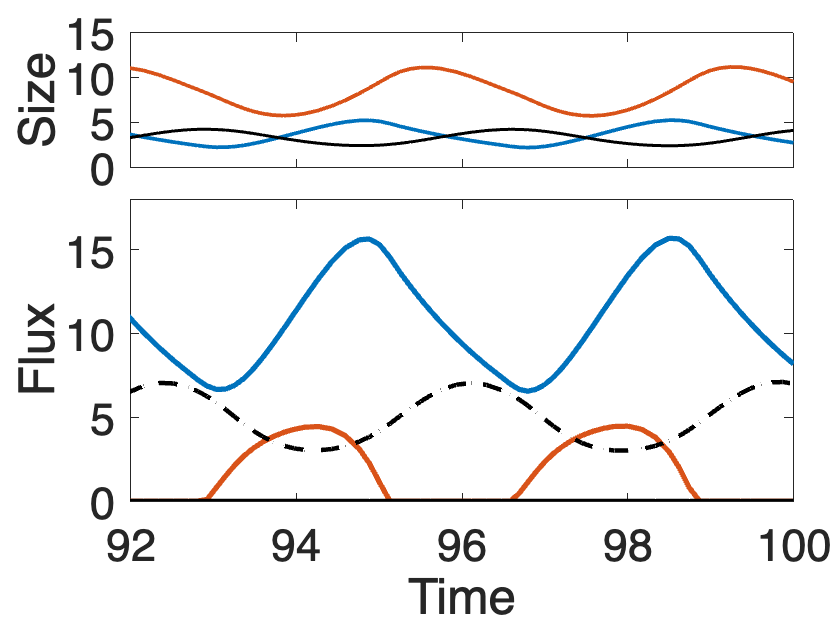

clear

%%% UNSTABLE
f = 3;
uJ = 0.5;
m = 2.5;
beta = 0.18;
a = 1;
mI = 1.5;
uA = 0.5;
mb = 0.2;
mbI = mb;

 N = ones(3,1);
 T_interval = [0, 100];
 Init_conditions = [9; 0.1; 3].*N;
    
[T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
[pksJS,locsJS] = findpeaks(N(:,1),T);
[pksJI,locsJI] = findpeaks(N(:,2),T);
[pksA,locsA] = findpeaks(N(:,3),T);
[pksJS2,locsJS2] = findpeaks(max(N(:,1))-N(:,1),T);
[pksJI2,locsJI2] = findpeaks(max(N(:,2))-N(:,2),T);
[pksA2,locsA2] = findpeaks(max(N(:,3))-N(:,3),T);


% plot(T,N, "LineWidth",3)
% hold on
% % xline(locsJS(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% legend("JS", "JI", "A")
% xlim([92 100])
% xlabel("Time")
% ylabel("Abundance")
% set(gca, 'FontSize', 30)
% hold off

colors = get(gca,'ColorOrder');
NN = N(:,1)+N(:,2);
NS = max(m-mb.*(NN),0);
NI = max(mI-mbI.*(NN),0);

tiledlayout(3,1,'TileSpacing','Compact', "Padding",'Compact')
nexttile
plot(T,N(:,1),"LineWidth",2.5, 'Color', colors(2,:))
hold on
plot(T,N(:,3),"LineWidth",2.5, 'Color', colors(1,:))
plot(T,N(:,2),"LineWidth",2, 'Color', "k")
xlim([92 100])
ylim([0 15])
%xlabel("Time")
ylabel("Size")
set(gca, 'FontSize', 30, 'Xticklabel',[])
%legend("J", "A_S", "A_I")
hold off

nexttile([2,1])
plot(T, NS.*N(:,1),"LineWidth",3.5, 'Color', colors(2,:)) %, "LineStyle","--") %% Total flux
hold on
plot(T, NI.*N(:,2),"LineWidth",3, 'Color', "k") %, "LineStyle","--") %% Total flux
plot(T, f*N(:,3),"LineWidth",3.5, 'Color', colors(1,:)) %, "LineStyle","--") %% Total flux
plot(T, beta*N(:,1).*N(:,2),"LineWidth",3, 'Color', "k", "LineStyle", "--") %, "LineStyle","--") %% Total flux
xlim([92 100])
ylim([0 18])
xlabel("Time")
ylabel("Flux")
set(gca, 'FontSize', 30)
hold off

%legend("JS->A", "JI->A", "A->JS", "JS->JI")


## Figure SI.1.5C

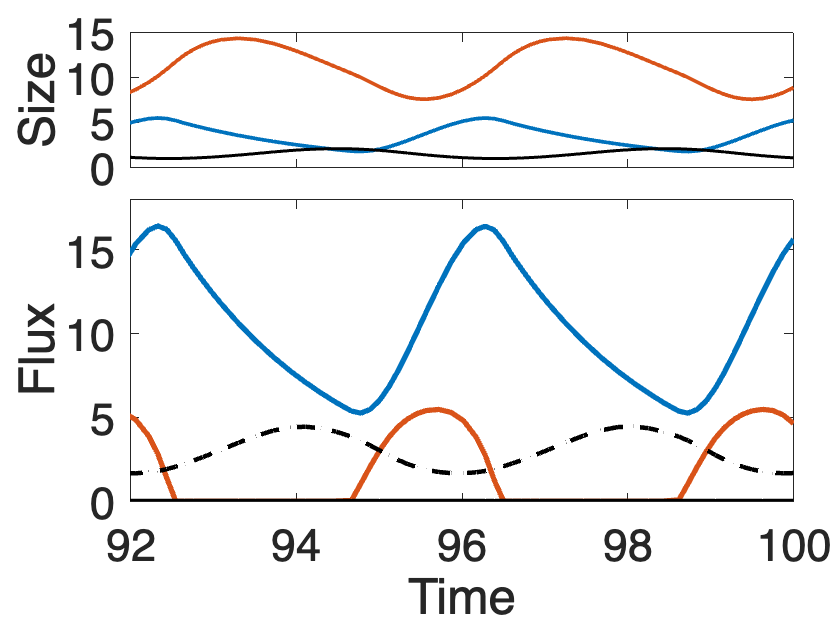

clear

%%% UNSTABLE
f = 3;
uJ = 0.5;
m = 2.5;
beta = 0.18;
a = 1.5;
mI = 1.5;
uA = 0.5;
mb = 0.2;
mbI = mb;

 N = ones(3,1);
 T_interval = [0, 100];
 Init_conditions = [9; 0.1; 3].*N;
    
[T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
[pksJS,locsJS] = findpeaks(N(:,1),T);
[pksJI,locsJI] = findpeaks(N(:,2),T);
[pksA,locsA] = findpeaks(N(:,3),T);
[pksJS2,locsJS2] = findpeaks(max(N(:,1))-N(:,1),T);
[pksJI2,locsJI2] = findpeaks(max(N(:,2))-N(:,2),T);
[pksA2,locsA2] = findpeaks(max(N(:,3))-N(:,3),T);


% plot(T,N, "LineWidth",3)
% hold on
% % xline(locsJS(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA2(3), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJS2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsJI2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% % xline(locsA2(4), "LineStyle","--", "LineWidth",2.5, "Color", "k")
% legend("JS", "JI", "A")
% xlim([92 100])
% xlabel("Time")
% ylabel("Abundance")
% set(gca, 'FontSize', 30)
% hold off

colors = get(gca,'ColorOrder');
NN = N(:,1)+N(:,2);
NS = max(m-mb.*(NN),0);
NI = max(mI-mbI.*(NN),0);

tiledlayout(3,1,'TileSpacing','Compact', "Padding",'Compact')
nexttile
plot(T,N(:,1),"LineWidth",2.5, 'Color', colors(2,:))
hold on
plot(T,N(:,3),"LineWidth",2.5, 'Color', colors(1,:))
plot(T,N(:,2),"LineWidth",2, 'Color', "k")
xlim([92 100])
ylim([0 15])
%xlabel("Time")
ylabel("Size")
set(gca, 'FontSize', 30, 'Xticklabel',[])
%legend("J", "A_S", "A_I")
hold off

nexttile([2,1])
plot(T, NS.*N(:,1),"LineWidth",3.5, 'Color', colors(2,:)) %, "LineStyle","--") %% Total flux
hold on
plot(T, NI.*N(:,2),"LineWidth",3, 'Color', "k") %, "LineStyle","--") %% Total flux
plot(T, f*N(:,3),"LineWidth",3.5, 'Color', colors(1,:)) %, "LineStyle","--") %% Total flux
plot(T, beta*N(:,1).*N(:,2),"LineWidth",3, 'Color', "k", "LineStyle", "--") %, "LineStyle","--") %% Total flux
xlim([92 100])
ylim([0 18])
xlabel("Time")
ylabel("Flux")
set(gca, 'FontSize', 30)
hold off

%legend("JS->A", "JI->A", "A->JS", "JS->JI")


## Figure SI.1.5D

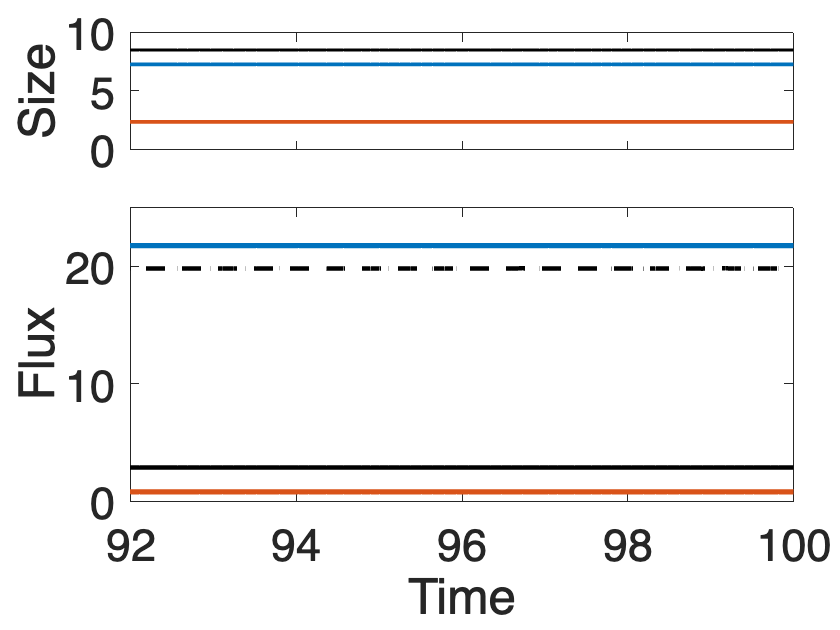

%%% UNSTABLE
f = 3;
uJ = 0.5;
m = 2.5;
beta = 1;
a = 1.5;
mI = 2.5;
uA = 0.5;
mb = 0.2;
mbI = mb;

 N = ones(3,1);
 T_interval = [0, 100];
 Init_conditions = [9; 0.1; 3].*N;
    
[T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
[pksJS,locsJS] = findpeaks(N(:,1),T);
[pksJI,locsJI] = findpeaks(N(:,2),T);
[pksA,locsA] = findpeaks(N(:,3),T);
[pksJS2,locsJS2] = findpeaks(max(N(:,1))-N(:,1),T);
[pksJI2,locsJI2] = findpeaks(max(N(:,2))-N(:,2),T);
[pksA2,locsA2] = findpeaks(max(N(:,3))-N(:,3),T);



colors = get(gca,'ColorOrder');
NN = N(:,1)+N(:,2);
NS = max(m-mb.*(NN),0);
NI = max(mI-mbI.*(NN),0);

tiledlayout(3,1,'TileSpacing','Compact', "Padding",'Compact')
nexttile
plot(T,N(:,1),"LineWidth",2.5, 'Color', colors(2,:))
hold on
plot(T,N(:,3),"LineWidth",2.5, 'Color', colors(1,:))
plot(T,N(:,2),"LineWidth",2, 'Color', "k")
xlim([92 100])
ylim([0 10])
%xlabel("Time")
ylabel("Size")
set(gca, 'FontSize', 30, 'Xticklabel',[])
%legend("J", "A_S", "A_I")
hold off

nexttile([2,1])
plot(T, NS.*N(:,1),"LineWidth",3.5, 'Color', colors(2,:)) %, "LineStyle","--") %% Total flux
hold on
plot(T, NI.*N(:,2),"LineWidth",3, 'Color', "k") %, "LineStyle","--") %% Total flux
plot(T, f*N(:,3),"LineWidth",3.5, 'Color', colors(1,:)) %, "LineStyle","--") %% Total flux
plot(T, beta*N(:,1).*N(:,2),"LineWidth",3, 'Color', "k", "LineStyle", "--") %, "LineStyle","--") %% Total flux
xlim([92 100])
ylim([0 25])
xlabel("Time")
ylabel("Flux")
set(gca, 'FontSize', 30)
hold off

%legend("JS->A", "JI->A", "A->JS", "JS->JI")


## Figure SI.1.5E

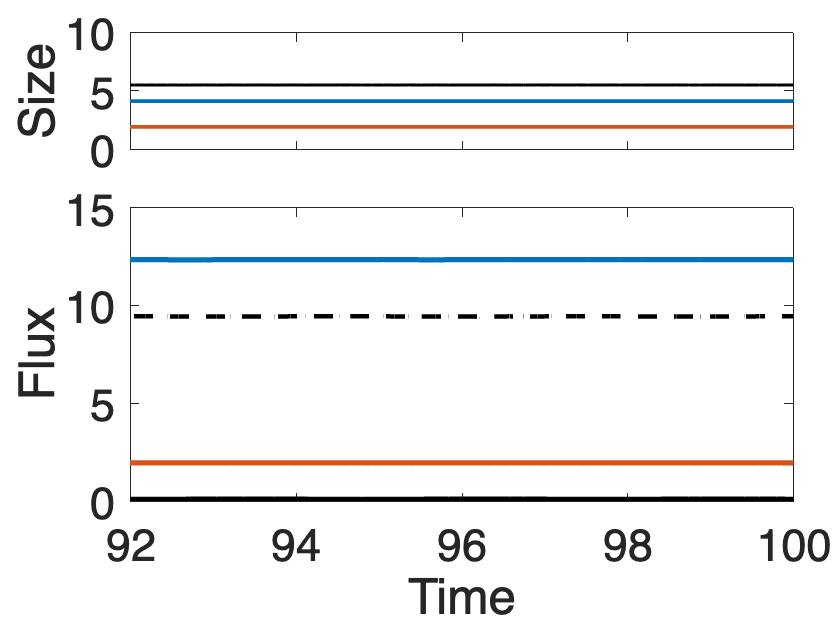

%%% UNSTABLE
f = 3;
uJ = 0.5;
m = 2.5;
beta = 0.9;
a = 1.2;
mI = 1.5;
uA = 0.5;
mb = 0.2;
mbI = mb;

 N = ones(3,1);
 T_interval = [0, 100];
 Init_conditions = [9; 0.1; 3].*N;
    
[T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
[pksJS,locsJS] = findpeaks(N(:,1),T);
[pksJI,locsJI] = findpeaks(N(:,2),T);
[pksA,locsA] = findpeaks(N(:,3),T);
[pksJS2,locsJS2] = findpeaks(max(N(:,1))-N(:,1),T);
[pksJI2,locsJI2] = findpeaks(max(N(:,2))-N(:,2),T);
[pksA2,locsA2] = findpeaks(max(N(:,3))-N(:,3),T);


colors = get(gca,'ColorOrder');
NN = N(:,1)+N(:,2);
NS = max(m-mb.*(NN),0);
NI = max(mI-mbI.*(NN),0);

tiledlayout(3,1,'TileSpacing','Compact', "Padding",'Compact')
nexttile
plot(T,N(:,1),"LineWidth",2.5, 'Color', colors(2,:))
hold on
plot(T,N(:,3),"LineWidth",2.5, 'Color', colors(1,:))
plot(T,N(:,2),"LineWidth",2, 'Color', "k")
xlim([92 100])
ylim([0 10])
%xlabel("Time")
ylabel("Size")
set(gca, 'FontSize', 30, 'Xticklabel',[])
%legend("J", "A_S", "A_I")
hold off

nexttile([2,1])
plot(T, NS.*N(:,1),"LineWidth",3.5, 'Color', colors(2,:)) %, "LineStyle","--") %% Total flux
hold on
plot(T, NI.*N(:,2),"LineWidth",3, 'Color', "k") %, "LineStyle","--") %% Total flux
plot(T, f*N(:,3),"LineWidth",3.5, 'Color', colors(1,:)) %, "LineStyle","--") %% Total flux
plot(T, beta*N(:,1).*N(:,2),"LineWidth",3, 'Color', "k", "LineStyle", "--") %, "LineStyle","--") %% Total flux
xlim([92 100])
ylim([0 15])
xlabel("Time")
ylabel("Flux")
set(gca, 'FontSize', 30)
hold off

%legend("JS->A", "JI->A", "A->JS", "JS->JI")



## Figure SI.1.5F

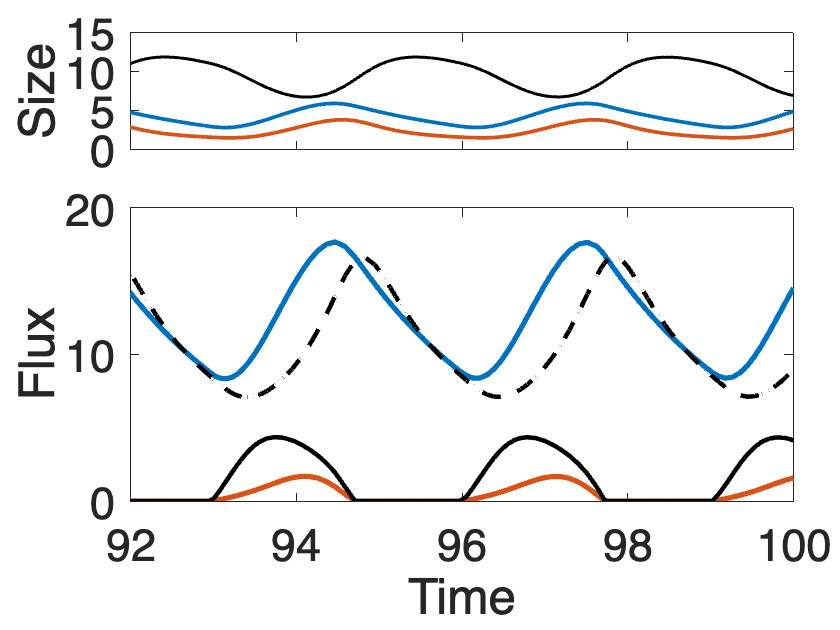

%%% UNSTABLE
f = 3;
uJ = 0.5;
m = 2.5;
beta = 0.5;
a = 0.5;
mI = 2.5;
uA = 0.5;
mb = 0.2;
mbI = mb;

 N = ones(3,1);
 T_interval = [0, 100];
 Init_conditions = [9; 0.1; 3].*N;
    
[T, N] = ode45(@(t,N)  pathogen_attacks_J_wMat_mb(t,N,f,uJ,m,beta,a,mI,uA,mb,mbI), T_interval, Init_conditions);
[pksJS,locsJS] = findpeaks(N(:,1),T);
[pksJI,locsJI] = findpeaks(N(:,2),T);
[pksA,locsA] = findpeaks(N(:,3),T);
[pksJS2,locsJS2] = findpeaks(max(N(:,1))-N(:,1),T);
[pksJI2,locsJI2] = findpeaks(max(N(:,2))-N(:,2),T);
[pksA2,locsA2] = findpeaks(max(N(:,3))-N(:,3),T);



colors = get(gca,'ColorOrder');
NN = N(:,1)+N(:,2);
NS = max(m-mb.*(NN),0);
NI = max(mI-mbI.*(NN),0);

tiledlayout(3,1,'TileSpacing','Compact', "Padding",'Compact')
nexttile
plot(T,N(:,1),"LineWidth",2.5, 'Color', colors(2,:))
hold on
plot(T,N(:,3),"LineWidth",2.5, 'Color', colors(1,:))
plot(T,N(:,2),"LineWidth",2, 'Color', "k")
xlim([92 100])
ylim([0 15])
%xlabel("Time")
ylabel("Size")
set(gca, 'FontSize', 30, 'Xticklabel',[])
%legend("J", "A_S", "A_I")
hold off

nexttile([2,1])
plot(T, NS.*N(:,1),"LineWidth",3.5, 'Color', colors(2,:)) %, "LineStyle","--") %% Total flux
hold on
plot(T, NI.*N(:,2),"LineWidth",3, 'Color', "k") %, "LineStyle","--") %% Total flux
plot(T, f*N(:,3),"LineWidth",3.5, 'Color', colors(1,:)) %, "LineStyle","--") %% Total flux
plot(T, beta*N(:,1).*N(:,2),"LineWidth",3, 'Color', "k", "LineStyle", "--") %, "LineStyle","--") %% Total flux
xlim([92 100])
ylim([0 20])
xlabel("Time")
ylabel("Flux")
set(gca, 'FontSize', 30)
hold off

%legend("JS->A", "JI->A", "A->JS", "JS->JI")